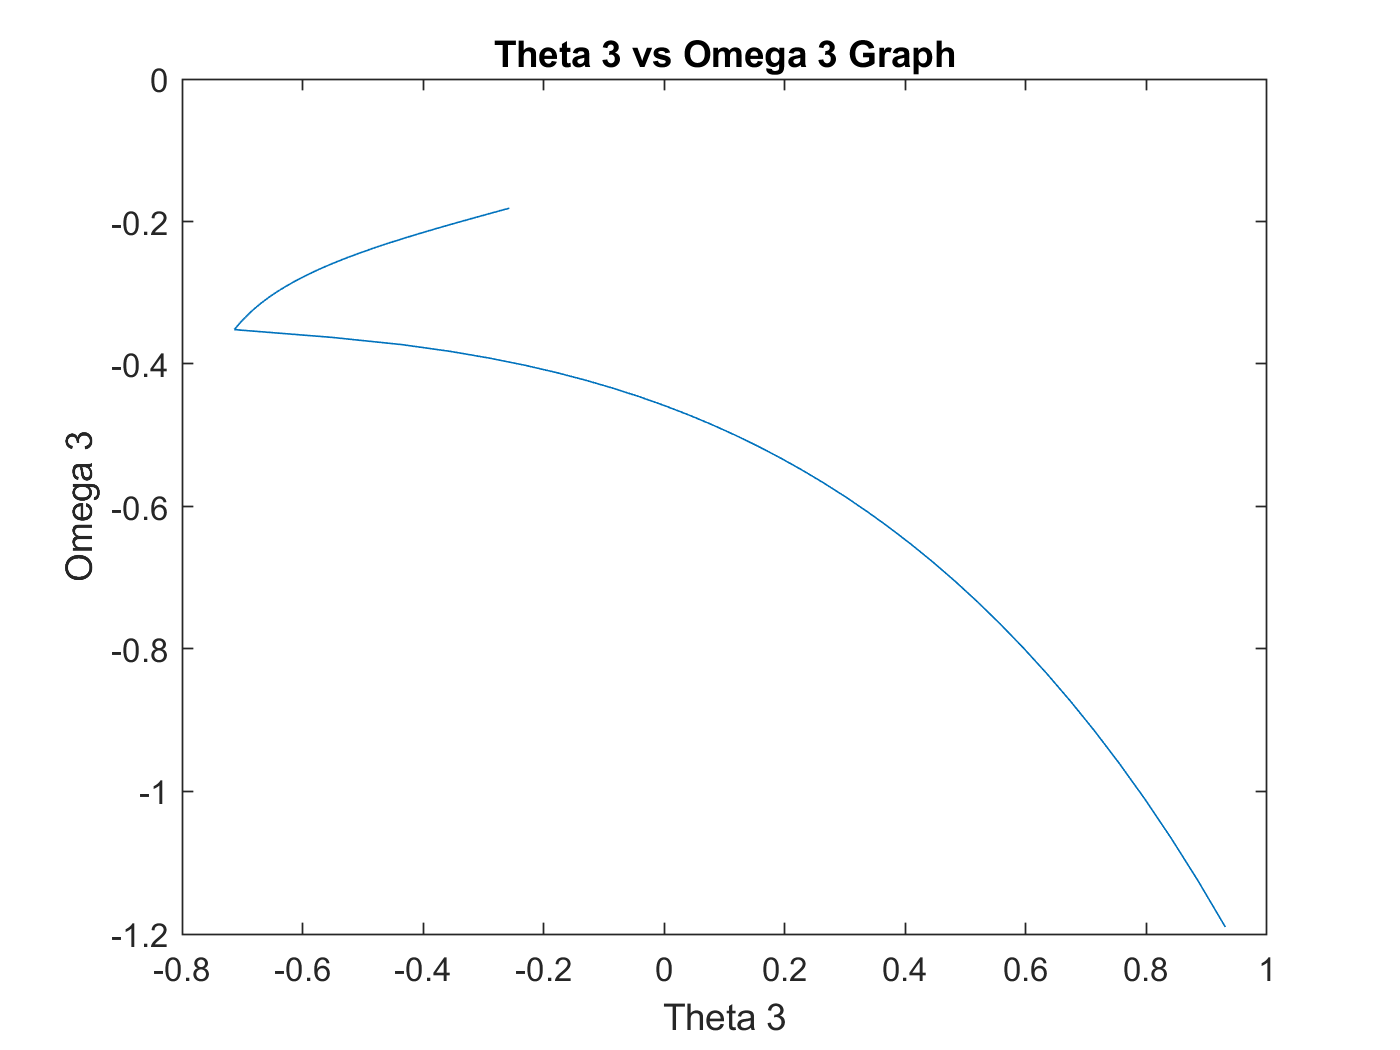

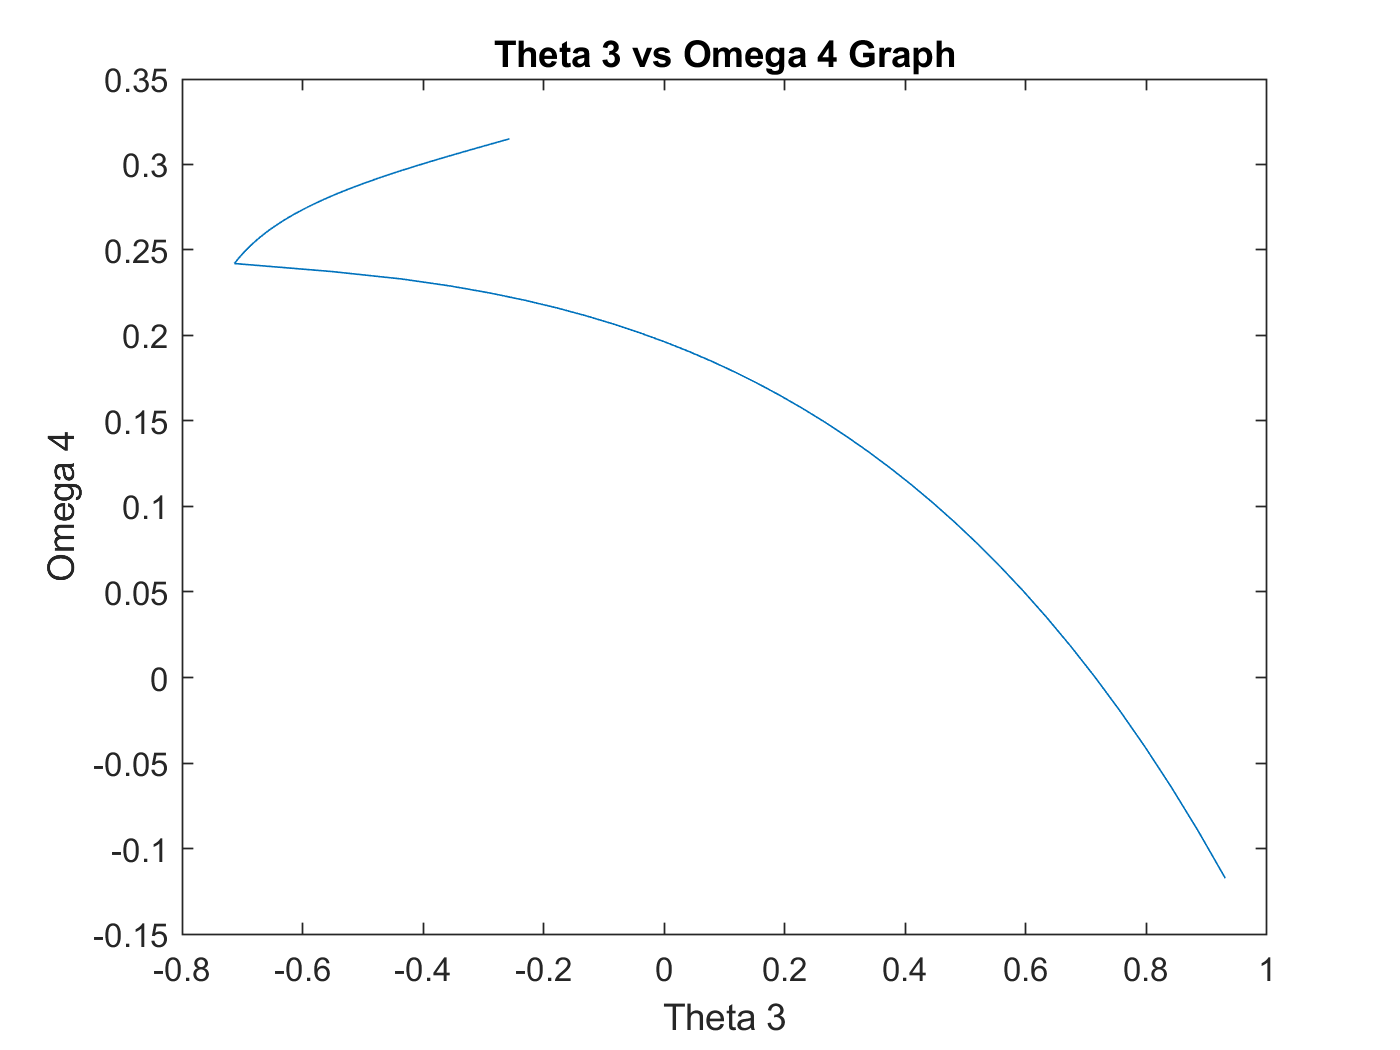

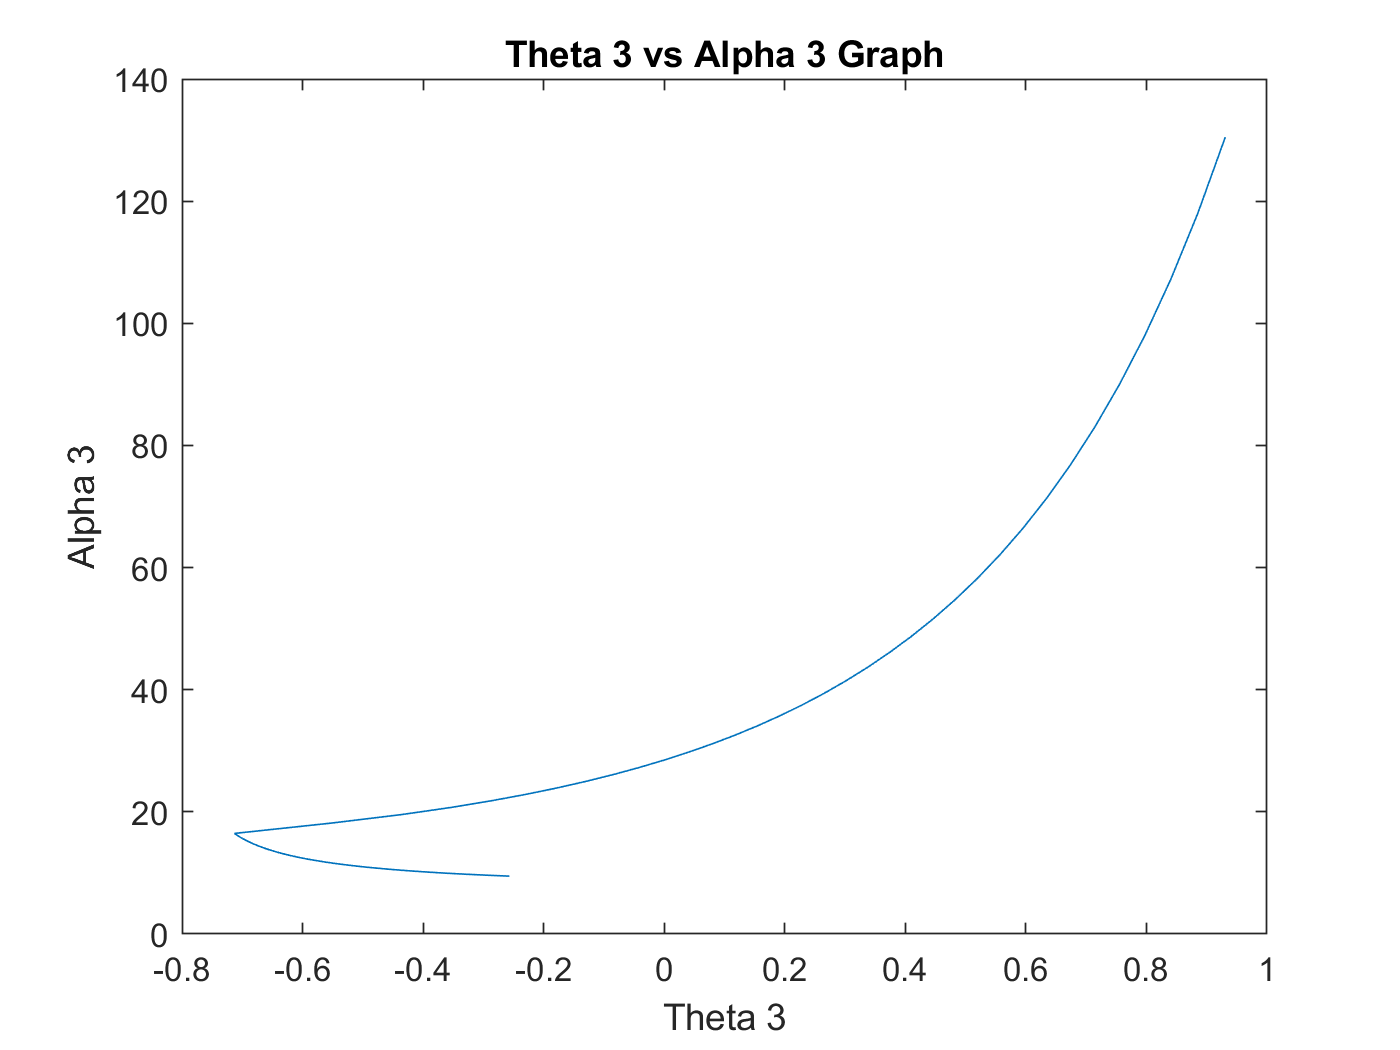

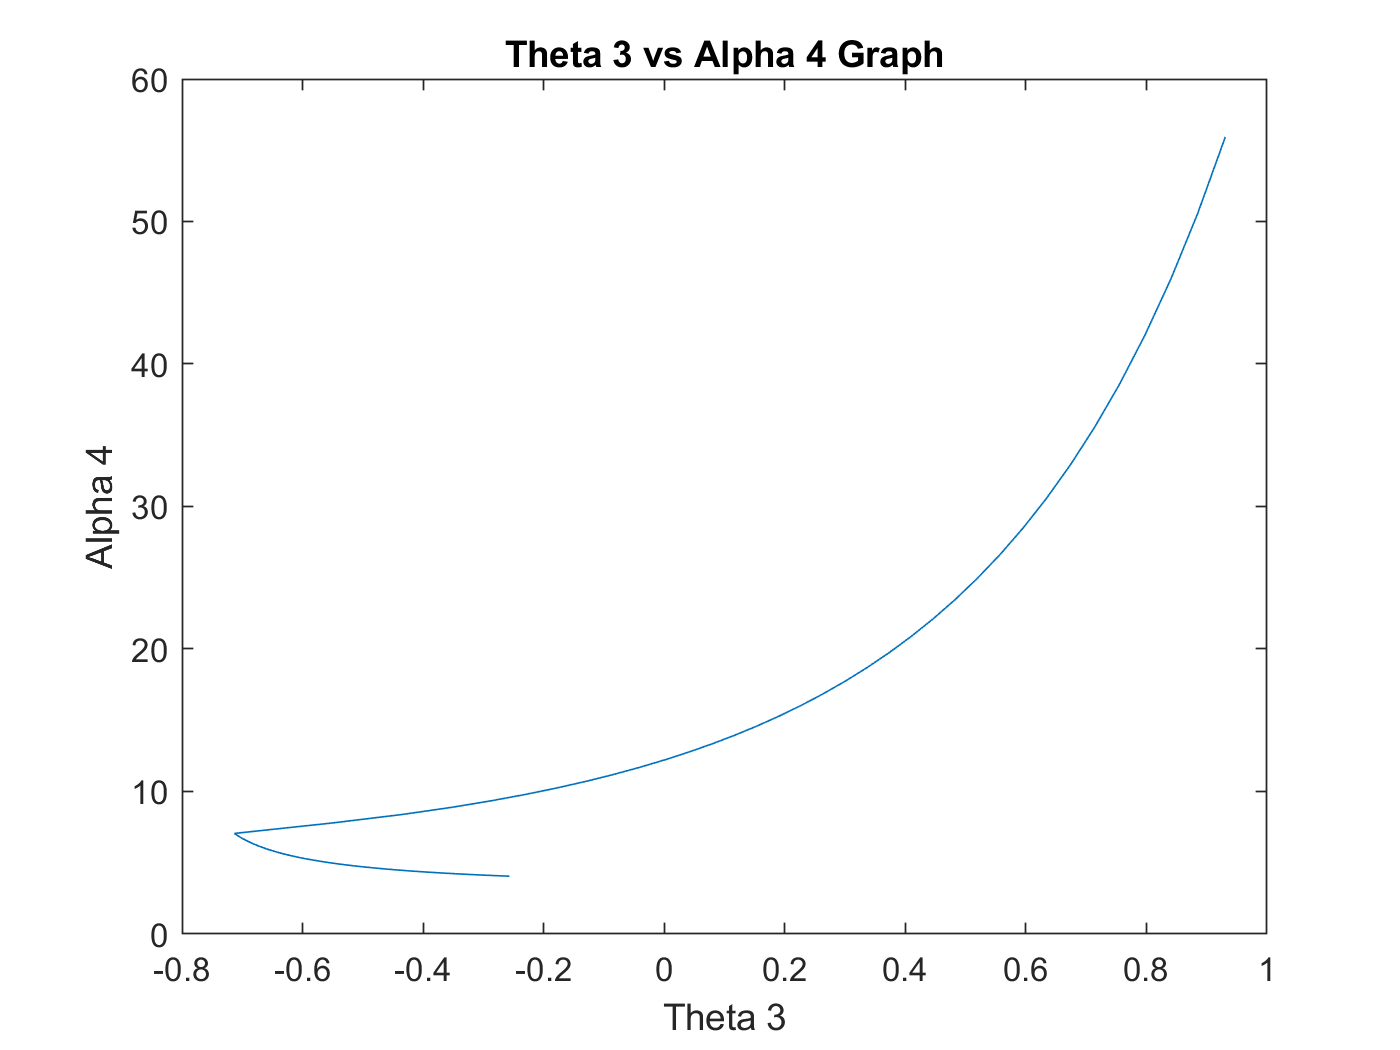

clear all;

R1 =10;
R2 =7; 
R3 =3;
R4 =7;
linkLengths = [R1 R2 R3 R4];
temp_linlLen = sort(linkLengths);
[theta1 , theta2, theta3, theta4] = calculateTheta(linkLengths);
[omega3, omega4] = calVel(linkLengths, theta2, theta3, theta4);
[alpha3, alpha4] = calAcc(linkLengths, theta2, theta3, theta4, omega3, omega4);
plotGraph(theta2, theta3, theta4, omega3, omega4, alpha3, alpha4);

function [theta1, theta2,theta3, theta4] =  calculateTheta(linkLengths)
    R1 = linkLengths(1);
    R2 = linkLengths(2);
    R3 = linkLengths(3);
    R4 = linkLengths(4);
    t = 0:5/180:3;
    ang_speed = pi/5;
    theta2 = ang_speed*t + pi/5;
    theta1 = deg2rad(0);
    
    for i=1:length(theta2)
        Alpha(i) = sqrt(R1^2 + R2^2 -2*R1*R2*cos(theta2(i)));
        Beta(i) = acos( (R1^2 + Alpha(i)^2 - R2^2) / (2*R1*Alpha(i)));
        Gamma(i) = acos( (R4^2 + Alpha(i)^2 - R3^2) / (2*R4*Alpha(i)));
        Delta(i) = acos( (R3^2 + Alpha(i)^2 - R4^2) / (2*R3*Alpha(i)));
        theta3(i) = Delta(i)-(Beta(i)-theta1);
        theta4(i) = pi-Gamma(i)-(Beta(i)-theta1);
    end  
end

function[Omega_3, Omega_4] = calVel(linkLengths, Theta_2, Theta_3, Theta_4)
    syms omega_3 omega_4
    R1 = linkLengths(1);
    R2 = linkLengths(2);
    R3 = linkLengths(3);
    R4 = linkLengths(4);
    prompt = 'What is the Driver Velocity? ';
    omega_2 = input(prompt);
    for i=1:length(Theta_2)
        theta2 = Theta_2(i);
        theta3 = Theta_3(i);
        theta4 = Theta_4(i);
        
        matA = [-R3*sind(theta3) R4*sind(theta4);R3*cosd(theta3) -R4*cosd(theta4)];
        matB = [R2*omega_2*sind(theta2);-R2*omega_2*cosd(theta2)];
        
        eqa = matA*[omega_3;omega_4] == matB;
        [omega3, omega4] = vpasolve(eqa,[omega_3 omega_4]);
        omega3 = double(omega3);
        omega4 = double(omega4);
        
        Omega_3(i) = omega3;
        Omega_4(i) = omega4;
     
    end
end

function [Alpha_3, Alpha_4] = calAcc(linkLengths, Theta_2, Theta_3, Theta_4, Omega_3, Omega_4)
    syms alpha_3 alpha_4
    R1 = linkLengths(1);
    R2 = linkLengths(2);
    R3 = linkLengths(3);
    R4 = linkLengths(4);
    omega_2 = pi/5;
    for i=1:length(Theta_2)
        theta2 = Theta_2(i);
        theta3 = Theta_3(i);
        theta4 = Theta_4(i);
        omega3 = Omega_3(i);
        omega4 = Omega_4(i);
        
        matA = [-R3*sind(theta3) R4*sind(theta4); R3*cosd(theta3) -R4*cosd(theta4)];
        matB = [R2*(omega_2^2)*cosd(theta2) + R3*(omega3^2)*cosd(theta3) - R4*(omega4^2)*cosd(theta4);
            R2*(omega_2^2)*sind(theta2) + R3*(omega3^2)*sind(theta3) - R4*(omega4^2)*sind(theta4)];
        
        eqa = matA*[alpha_3;alpha_4] == matB;
        [alpha3, alpha4] = vpasolve(eqa,[alpha_3 alpha_4]);
        Alpha_3(i) = double(alpha3);
        Alpha_4(i) = double(alpha4);
    end
end

function displayTable(theta2, theta3, theta4, omega3, omega4, alpha3, alpha4)
    table(theta2',theta3',theta4',omega3',omega4',alpha3',alpha4', 'VariableNames', {'Theta 2','Theta 3','Theta 4','Omega 3','Omega 4','Alpha 3','Alpha 4'})
end

function plotGraph(theta2, theta3, theta4, omega3, omega4, alpha3, alpha4)
    plot(theta3, omega3)
    title('Theta 3 vs Omega 3 Graph');
    xlabel('Theta 3')
    ylabel('Omega 3')
    figure;
    plot(theta3, omega4)
     title('Theta 3 vs Omega 4 Graph');
    xlabel('Theta 3')
    ylabel('Omega 4')
    figure;
    plot(theta3, alpha3)
     title('Theta 3 vs Alpha 3 Graph');
    xlabel('Theta 3')
    ylabel('Alpha 3')
    figure;
    plot(theta3, alpha4)
     title('Theta 3 vs Alpha 4 Graph');
    xlabel('Theta 3')
    ylabel('Alpha 4')
end




